# Çözmeye Çalıştığımız Problem

Pozisyon tahmininimizi yapabilmek için 3 ya da daha fazla uzaklık değerini kullanıyoruz.

İdeal ortamda baktığımızda 0 hata değeriyle 3 uzaklık değeri ile çizilen daireler 2 boyutta bize kesin bir konum tahmini yaptırabiliyor.

Ama gerçek hayatta gerek ölçüm hataları gerekse iç mekandan kaynaklanan yansıma veya absorbe durumları sebebiyle ideal ölçüm alamıyoruz. Bu da aşağıda gördüğümüz şekilde farklı durumlara yol açmakta.

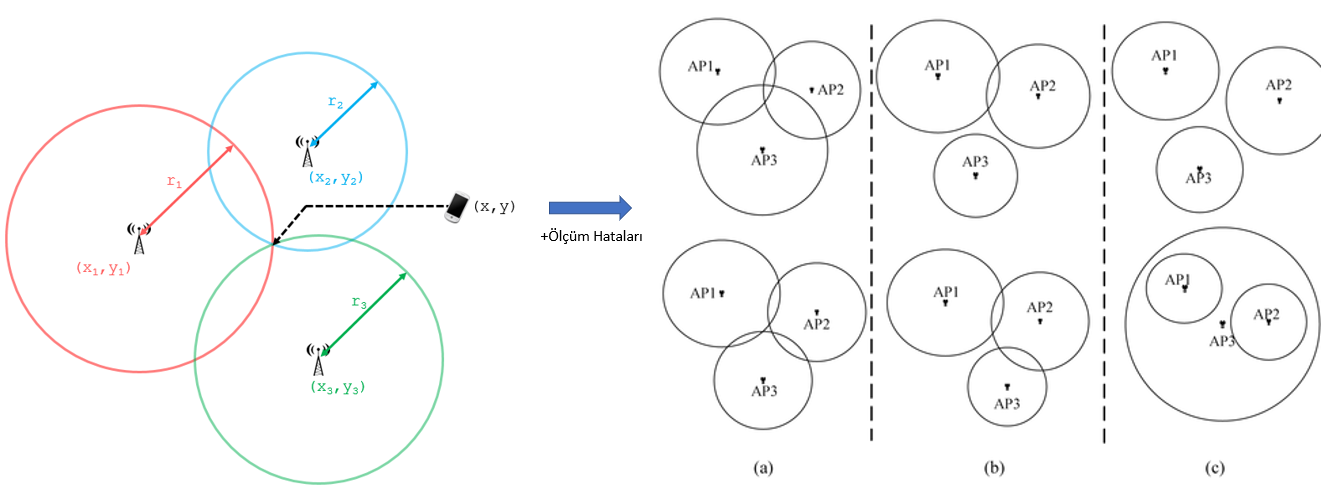

Biz de bu problemleri çözebilmek için aşağıdaki MATLAB ortamında aşağıdaki programı yazdık.

# Değişken Tanımlamaları 

## Genel Değişkenler

stddev = 0.4

stddev = 0.4000

variance = stddev^2

variance = 0.1600

Kullanıdığımız modelin standart sapması ve buna bağlı varyansı. 0 ile 1 metre arasında ayarlayabiliyoruz. Bu değeri "add_error" fonksiyonumuza göndererek aldığımız uzaklık değerlerini gerçek dünyada karşılaşmayı beklediğimiz hata payına göre hızlıca ayarlayabiliriz. 

delta_time = 10e-3; %10 Hertz

x_Anchor = [0 11 0 11]; % Anchorlar X koordinatları
y_Anchor = [0 0 11 11]; % Anchorlar Y koordinatları
Anchor_Koordinatlari = [x_Anchor ; y_Anchor ]

Anchor_Koordinatlari =      0    11     0    11
     0     0    11    11


Yerleştirdiğimiz anchorların x ve y koordinatları. En az 3 olacak şekilde isteğe göre ekleyip çıkarılabilir.

tag_real = [0 0]; % Gerçek tag değeri
tag_real(1) = 3;
tag_real(2) = 8;

Başlangıçta bulunmak istenilen pozisyon. Anchorların menzilden çıkması durumunda değiştirilebilir.

## Least Mean Square/Gradient Descent

Bu algoritma sayesinde aldığımız üç veya daha fazla uzaklık değerine kollektif olarak analiz ederek gerçek noktamız olma potansiyeli en yüksek olan noktayı buluyoruz. 

Girişte anlattığımız probleme dönersek:

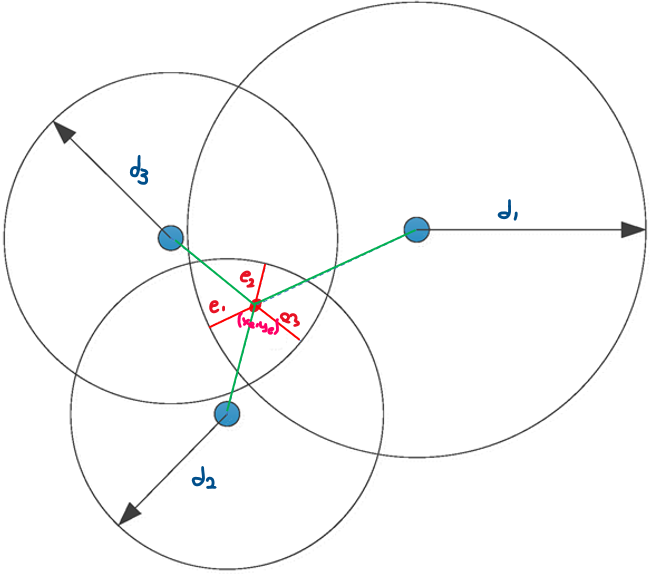 

$d_{1\;} ,d_2 \;\textrm{ve}\;d_3 \;$uzaklıkları ölçümlerden elde ettiğimiz ve bir gaussian distributiona sahip olduğunu varsaydığımız uzaklık değerleri.

$x_e \;\textrm{ve}\;y_{e\;} \;$ise test noktanızın koordinatları. Anchorlarımızın koordinatlarını da bildiğimize göre test noktamız ve anchorlar arasındaki mesafeyi hesaplayarak üstte gördüğümüz yeşil uzaklığı elde edebiliriz. Daha sonra $d_{1\;} ,d_2 \;\textrm{ve}\;d_3$ uzaklıklarını yeşil olarak gösterilen uzaklıklardan çıkardığımızda ise kırmızıyla gösterilmiş$\;e_1 ,e_2 \;\textrm{ve}\;e_3$ hata değerlerini elde ediyoruz. Peki bu hata değerlerinin minimum olduğu noktayı nasıl bulabiliriz? İşte bu noktada** Least Mean Squares(LMS) **ve dolaylı yoldan da **Gradient Descent** algoritmalarını kullanıyoruz.

Öncelikle negatif hata değerlerinin toplam hatayı 0 gibi göstermesini engellemek için hatanın ya mutlak değerini ya da karesini almamız gerekli. Mutlak değer her yerde türevlenebilir bir fonksiyon vermediğinden ve gradient hesaplanması gerektiğinden her hata değerinin karesini alarak topluyoruz.

Pseudo Algoritma:

1- Rastgele bir tahmin noktası seçme (x_e, y_e)

2- Bu noktadaki gradienti hesaplama

3- Gradientin tersi yönünde adım atmak: Yeni Tahmin = Eski Tahmin – step_size*$\frac{\partial\left(d_e\right)^2}{\partial x}$


$$d_e=\sqrt{\left(x_{a1}-x_e\right)^2+\left(y_{a1}-y_e\right)^2}\ -d_m\$$


$\frac{\partial d_e}{\partial x}=\frac{x_{a1}-x_e}{\sqrt{\left(x-x_e\right)^2+\left(y-y_e\right)^2}}=\frac{x_{a1}-x_e}{d_e}$  , $\frac{\partial d_e}{\partial y}= \frac{y_{a1}-y_e}{d_e} $

4- Yeni sonuçla ikiye atla 

Bu koşullarda yazdığımız fonksiyon:

N = 100; % Iterasyon sayisi
mu =0.1; % Step size

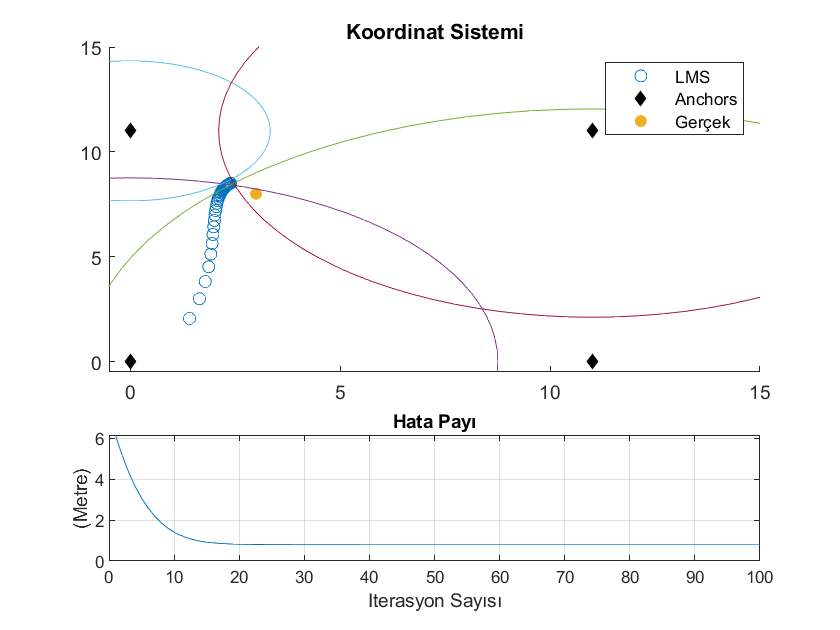


tag_estimated = [1 1]; % Initial guess

distance_real = calculateDistance(tag_real, x_Anchor,y_Anchor); % Gerçek uzaklık değerlerinin hesaplanması
distance_measured = add_error(distance_real,stddev); % Add 0 mean gaussian error


%Grafikler için -----------------------
figure;
subplot(3,1,[1,2]);
scatter1 = scatter(tag_estimated(1),tag_estimated(2));
hold on
anchor = scatter(x_Anchor,y_Anchor,'kd','filled');
hold on 
scatter2 = scatter(tag_real(1),tag_real(2),'filled');
circle(x_Anchor(1),y_Anchor(1),distance_measured(1));
circle(x_Anchor(2),y_Anchor(2),distance_measured(2));
circle(x_Anchor(3),y_Anchor(3),distance_measured(3));
circle(x_Anchor(4),y_Anchor(4),distance_measured(4));

legend("LMS","Anchors","Gerçek","","","","")
title("Koordinat Sistemi")
ylim([-0.5 15])
xlim([-0.5 15])
subplot(3,1,3);
plot_error = plot(calculateDistance(tag_estimated,tag_real(1),tag_real(2)));
title("Hata Payı");
ylabel("(Metre)");
xlabel("Iterasyon Sayısı")
grid on

%---------------------------------------------
for n = 1:N    
    % tag_estimated pozisyonunun her anchora olan uzaklığını 
    distance_estimated = calculateDistance(tag_estimated,x_Anchor,y_Anchor); 
    
    %Error_distance ın karesinin gradienti
    diff_Ex = sum((-2/3)*(1-distance_measured./distance_estimated).*(x_Anchor-tag_estimated(1))); % x e göre partial türev
    diff_Ey = sum((-2/3)*(1-distance_measured./distance_estimated).*(y_Anchor-tag_estimated(2))); % y ye göre partial türev

    %Erroru azaltmak için gradientin tersi yönde bir adım atarak bir minimum arıyoruz 
    tag_estimated(1)=tag_estimated(1)-mu*diff_Ex;
    tag_estimated(2)=tag_estimated(2)-mu*diff_Ey;  
    
    
    
    %Grafikler için ------------------------------------------------
    storex(n) = tag_estimated(1);
    storey(n) = tag_estimated(2);
    stored(n) = calculateDistance(tag_estimated,tag_real(1),tag_real(2));
    scatter1.XData = storex(1:n);
    scatter1.YData = storey(1:n); 
    plot_error.YData = stored(1:n);
    plot_error.XData = 1:n;
%     pause(0.0001);
end

Hata dağılımını bulmak için aynı koordinat için farklı hesaplamalar kullanabiliriz.

stddev_histogram = 1

stddev_histogram = 1

varyans = stddev_histogram^2

varyans = 1

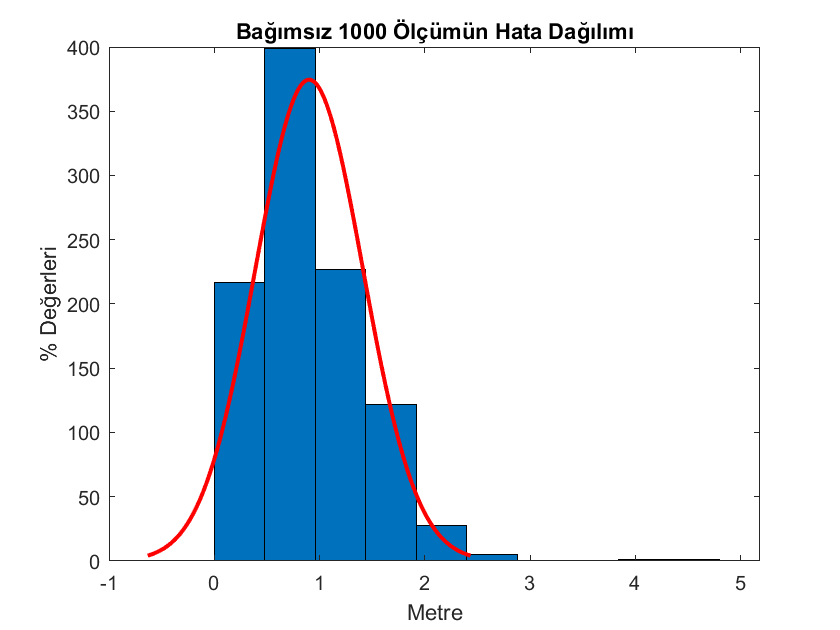

for k = 1:1000
    distance_measured = add_error(distance_real,stddev_histogram);
    tag_estimated_LMS = LMS_EstimatePoint(distance_measured,x_Anchor,y_Anchor);
    lms_error_histogram(k) = calculateDistance(tag_estimated_LMS,tag_real(1),tag_real(2));
end
figure;
histfit(lms_error_histogram,10);
title("Bağımsız " + k + " Ölçümün Hata Dağılımı");
xlabel('Metre'); 
ylabel('% Değerleri'); 

pd = fitdist(lms_error_histogram','Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0.901322   [0.869604, 0.93304]
    sigma = 0.511135   [0.489674, 0.534578]


type = "nakagami"

type = "nakagami"

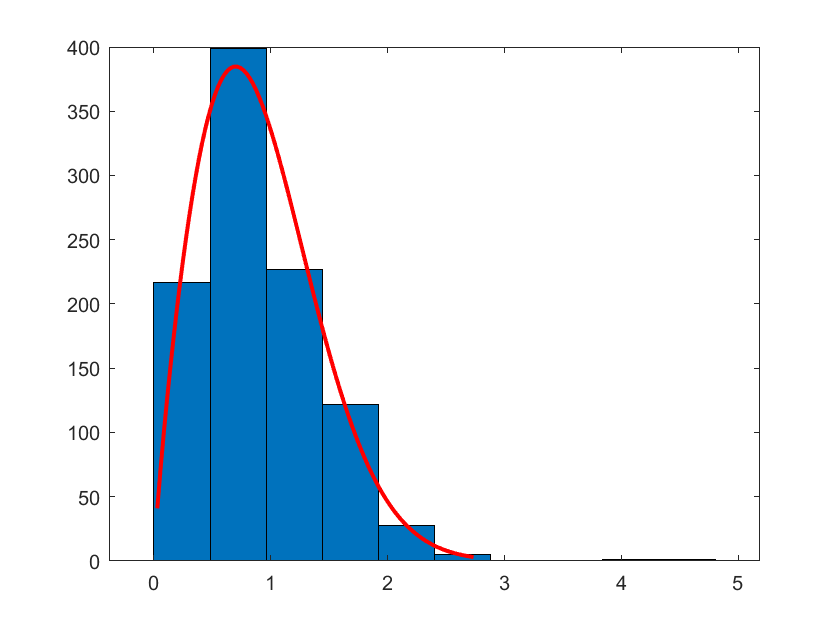

figure;
histfit(lms_error_histogram,10,type);

pd = fitdist(lms_error_histogram',type)

pd =   NakagamiDistribution

  Nakagami distribution
       mu = 0.917577   [0.849928, 0.99061]
    omega =  1.07338   [1.00613, 1.14513]


## Kalman Filtresi  

Başlıca matrixler:

x_coordinate = 0;
y_coordinate = 0;
x_velocity = 0;
y_velocity = 0;
x_acceleration = 0;
y_acceleration = 0;

X_state_matrix =...
    [x_coordinate
    x_velocity
    x_acceleration
    y_coordinate
    y_velocity
    y_acceleration];

$\textrm{State}\;\textrm{Matrix}={\left[\begin{array}{c}
x\\
y\\
\dot{\begin{array}{c}
x\\
\dot{\begin{array}{c}
y\\
\ddot{x} \\
\ddot{y} 
\end{array}} 
\end{array}} 
\end{array}\right]}\;$ İki koordinatta pozisyon, hız ve ivme değişkenleri içeren 6x1 bir vektörümüz var. Biz sadece x ve y koordinatlarını input olarak almamıza rağmen geniş state matriximiz sayesinde ivme ve hız değerleri de hesaplamaya katılarak gelecek konum tahmini daha hassas bir şekilde yapılıyor.

F_state_transition_matrix = ...
    [1 delta_time   (delta_time^2)/2    0 0          0
    0 1            delta_time          0 0          0
    0 0            1                   0 0          0
    0 0            0                   1 delta_time (delta_time^2)/2
    0 0            0                   0 1           delta_time
    0 0            0                   0 0           1];

State transition matriximiz koordinat, hız ve ivme değerlerinin fiziksel modellerini içerir. 

Q_process_noise_matrix = variance*...
    [(delta_time^4)/4 (delta_time^3)/2 (delta_time^2)/2 0                 0               0
    (delta_time^3)/2 (delta_time^2)    delta_time      0                 0               0
    (delta_time^2)/2 (delta_time)      1               0                 0               0
    0                 0                0               (delta_time^4)/4 (delta_time^3)/2 (delta_time^2)/2
    0                 0                0               (delta_time^3)/2 (delta_time^2)   delta_time
    0                 0                0               (delta_time^2)/2 (delta_time)      1];

H_observation_matrix = [1 0 0 0 0 0 ; 0 0 0 1 0 0];

Sadece x ve y koordinatları gözlemlememizi sağlayan observation matrix

Z_measurement_matrix = [0; 0];
R_measurement_covariance = [variance 0 ; 0 variance];

P_initial_covariance_matrix = eye(6)*100;

P_predicted_covariance_matrix = F_state_transition_matrix*P_initial_covariance_matrix*F_state_transition_matrix' + Q_process_noise_matrix;

X_state_matrix = F_state_transition_matrix*X_state_matrix;


Kalman filtremiz iki aşamadan oluşuyor: 

**Update**

Gain Hesaplama: $K_{n}=P H^{T}\left(H PH^{T}+R\right)^{-1}$

Durumun Tahmini: $
\hat{x}_{new}=\hat{x}_{old}+K\left(z-H \hat{x}_{old}\right)
$

Şu Anki Tahmine Olan Güvenin Hesabı: $
P=\left(I-K H\right) P\left(I-KH\right)^{T}+K R K^{T}$

**Predict**

Sıradaki Durumun Tahmini: $
\hat{{x}}_{\mathbf}={F} \hat{{x}}_{\mathbf}
$

Sıradaki Tahmine Olan Güvenin Hesabı: $P=F PF^{T}+Q$

tag_real(1) = 0;
tag_real(2) = 0;

stddev = 1

stddev = 1

variance = stddev^2

variance = 1

time_elapsed = 13

time_elapsed = 13

yol_tipi = "u donusu"

yol_tipi = "u donusu"

show_kalman_position = true

show_kalman_position = logical
   1


show_real_position = true

show_real_position = logical
   1


show_LMS_position = false

show_LMS_position = logical
   0


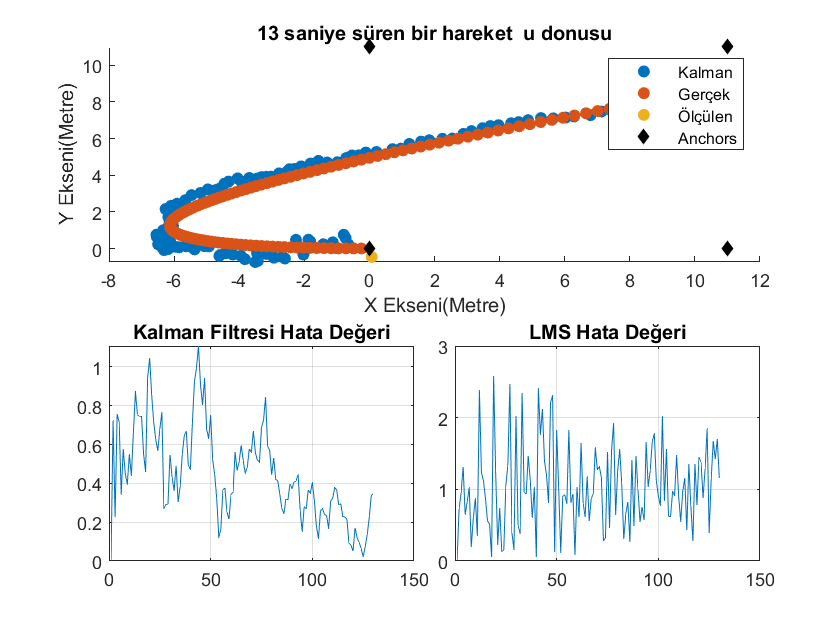



for k = 1:time_elapsed*10 %1 iterasyon = 0.1 saniye
    
    if yol_tipi == "sabit konum"
        tag_real = tag_real;
    elseif yol_tipi == "sabit hiz"
        tag_real(1) = tag_real(1) + 1.5/10;
        tag_real(2) = tag_real(2) + 1.5/10;
    elseif yol_tipi == "sabit ivme"
        tag_real(1) = tag_real(1) + 0.002*k;
        tag_real(2) = tag_real(2) + 0.002*k;
    elseif yol_tipi == "dairesel"
        tag_real(1) = 5*cos(k/10)+7;
        tag_real(2) = 5*sin(k/10)+7;
    elseif yol_tipi == "u donusu"
        tag_real(1) = tag_real(1) + 1/10*((k-50)/20);
        tag_real(2) = tag_real(2) +0.001*k;
    end
    
    %Olcum al
    distance_measured = take_measurement(tag_real,x_Anchor,y_Anchor,stddev);
    
    %Least mean square'e sok
    tag_estimated_LMS = LMS_EstimatePoint(distance_measured,x_Anchor,y_Anchor);
    
    
    
    %Olcumleri kaydet (gereksiz ama dursun)
    Z_measurement_matrix = tag_estimated_LMS';
    
    %Gain hesaplama
    K_kalman_gain = P_predicted_covariance_matrix*H_observation_matrix'*...
        inv(H_observation_matrix*P_predicted_covariance_matrix*H_observation_matrix' + R_measurement_covariance);
    
    %State matrixin guncellenmesi
    X_state_matrix = X_state_matrix + ...
        K_kalman_gain*(Z_measurement_matrix - H_observation_matrix*X_state_matrix);
    
    %Beklenen yeni hata payi matrixi
    P_predicted_covariance_matrix = (eye(6) - K_kalman_gain*H_observation_matrix)*...
        P_predicted_covariance_matrix*(eye(6)-K_kalman_gain*H_observation_matrix)' + ...
        K_kalman_gain*R_measurement_covariance*K_kalman_gain';
    
    %
    X_state_matrix = F_state_transition_matrix*X_state_matrix;
    
    P_predicted_covariance_matrix = F_state_transition_matrix*...
        P_predicted_covariance_matrix*F_state_transition_matrix' + Q_process_noise_matrix;
    
    
    %Grafikler için --------------------------------------------------------
    x_kalman_temp(k) = X_state_matrix(1);
    y_kalman_temp(k) = X_state_matrix(4);
    
    x_raw_temp(k) = tag_real(1);
    y_raw_temp(k) = tag_real(2);
    
    x_measured_temp(k) = Z_measurement_matrix(1);
    y_measured_temp(k) = Z_measurement_matrix(2);
end

draw(x_kalman_temp, y_kalman_temp, x_raw_temp, x_measured_temp, y_measured_temp, x_Anchor, y_Anchor, time_elapsed, yol_tipi, k, y_raw_temp, show_real_position, show_kalman_position, show_LMS_position);

function h = circle(x,y,r)
hold on
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end

function draw(x_kalman_temp, y_kalman_temp, x_raw_temp, x_measured_temp, y_measured_temp, x_Anchor, y_Anchor, time_elapsed, yol_tipi, k, y_raw_temp, show_real_position, show_kalman_position, show_LMS_position)
f = figure;
subplot(2,4,[1,2,3,4]);
scatter_kalman_pos = scatter(x_kalman_temp(1),y_kalman_temp(1),'filled');
hold on
scatter_real_pos = scatter(x_raw_temp(1),x_raw_temp(1),'filled');
hold on
scatter_lms_pos = scatter(x_measured_temp(1),y_measured_temp(1),'filled');
hold on
scatter_anchor = scatter(x_Anchor,y_Anchor,'kd','filled');
legend("Kalman","Gerçek","Ölçülen", "Anchors")
title(time_elapsed + " saniye süren bir hareket  " + yol_tipi)
xlabel('X Ekseni(Metre)');
ylabel('Y Ekseni(Metre)');

subplot(2,4,[5,6]);
plot_kalman_error = plot(calculateDistance([x_kalman_temp(abs(k-1)),y_kalman_temp(abs(k-1))],x_raw_temp(k),y_raw_temp(k)));
grid on
title('Kalman Filtresi Hata Değeri')
subplot(2,4,[7,8]);
plot_lms_error = plot(calculateDistance([x_measured_temp(abs(k-1)),y_measured_temp(abs(k-1))],x_raw_temp(k),y_raw_temp(k)));
grid on
title('LMS Hata Değeri')

for k = 2:(time_elapsed*10)
    subplot(2,4,[1,2,3,4]);
    
    if show_real_position == 1
        scatter_real_pos.XData = x_raw_temp(1:k);
        scatter_real_pos.YData = y_raw_temp(1:k);
    end
    if show_kalman_position == 1
        scatter_kalman_pos.XData = x_kalman_temp(1:k);
        scatter_kalman_pos.YData = y_kalman_temp(1:k);
    end
    if show_LMS_position == 1
        scatter_lms_pos.XData = x_measured_temp(1:k);
        scatter_lms_pos.YData = y_measured_temp(1:k);
    end
    pause(0.000001)
    % draw stuff
    subplot(2,4,[5,6]);
    hata_lms(k) = calculateDistance([x_measured_temp(abs(k-1)),y_measured_temp(abs(k-1))],x_raw_temp(k),y_raw_temp(k));
    plot_lms_error.YData = hata_lms(1:k);
    plot_lms_error.XData = 1:k;
    subplot(2,4,[7,8]);
    hata_kalman(k) = calculateDistance([x_kalman_temp(abs(k-1)),y_kalman_temp(abs(k-1))],x_raw_temp(k),y_raw_temp(k));
    plot_kalman_error.YData = hata_kalman(1:k);
    plot_kalman_error.XData = 1:k;
end
end